% load('Controllers/PolePlacementWout/DT_SS_model_G1.mat')
% A = G1.A
% B = G1.B
% C = G1.C
% D = G1.D

Load ss matrices

A = [       -50,        0,         0,        0,       0;
              0,        0,         1,        0,       0;
        49.7348,   2.5645, -419.7870,  -1.7769,  0.0023;
              0,        0,         0,        0,       1;
      -109.4970, 124.5290,  924.2091, 134.0870, -0.0972];
 
B = [-2.9990e+03; 0; 0; 0; 0]

B =        -2999
           0
           0
           0
           0



C = [0 1 0 0 0;
     0 0 0 1 0];
 
D = [0; 0];

create state space object

sys = ss(A, B, C, D)


sys =
 
  A = 
            x1       x2       x3       x4       x5
   x1      -50        0        0        0        0
   x2        0        0        1        0        0
   x3    49.73    2.564   -419.8   -1.777   0.0023
   x4        0        0        0        0        1
   x5   -109.5    124.5    924.2    134.1  -0.0972
 
  B = 
          u1
   x1  -2999
   x2      0
   x3      0
   x4      0
   x5      0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   1   0   0   0
   y2   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



% sys = d2c(sys)

check controlable

Co = ctrb(sys)

Co = 	1.0e+13 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0019
         0         0   -0.0000    0.0000   -0.0030
         0   -0.0000    0.0000   -0.0030    1.2524
         0         0    0.0000   -0.0000    0.0066
         0    0.0000   -0.0000    0.0066   -2.7591


unco = length(A) - rank(Co)

unco = 0

check open loop eigenvalues

E = eig(A)

E =  -419.8075
   11.3659
  -11.4529
    0.0103
  -50.0000


Desired closed loop eigenvalues

% P = [-0.1 -0.2 -0.3 -0.4 -0.6 -0.8]
P = [-0.1 -0.2 -0.3 -0.4 -0.8];

solve for K

K = place(A, B, P)

K =     0.1561    0.0085   -1.1760   -0.0037    0.0008


check for closed loop eigenvalues

A_cl = A - B*K

A_cl = 	1.0e+03 *

    0.4181    0.0254   -3.5267   -0.0111    0.0023
         0         0    0.0010         0         0
    0.0497    0.0026   -0.4198   -0.0018    0.0000
         0         0         0         0    0.0010
   -0.1095    0.1245    0.9242    0.1341   -0.0001


Create closed loop system

syscl = ss(A_cl, B, C, D)


syscl =
 
  A = 
            x1       x2       x3       x4       x5
   x1    418.1    25.44    -3527   -11.05    2.252
   x2        0        0        1        0        0
   x3    49.73    2.564   -419.8   -1.777   0.0023
   x4        0        0        0        0        1
   x5   -109.5    124.5    924.2    134.1  -0.0972
 
  B = 
          u1
   x1  -2999
   x2      0
   x3      0
   x4      0
   x5      0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   1   0   0   0
   y2   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



% syscl = c2d(syscl)
% sys = c2d(sys)

chec step response

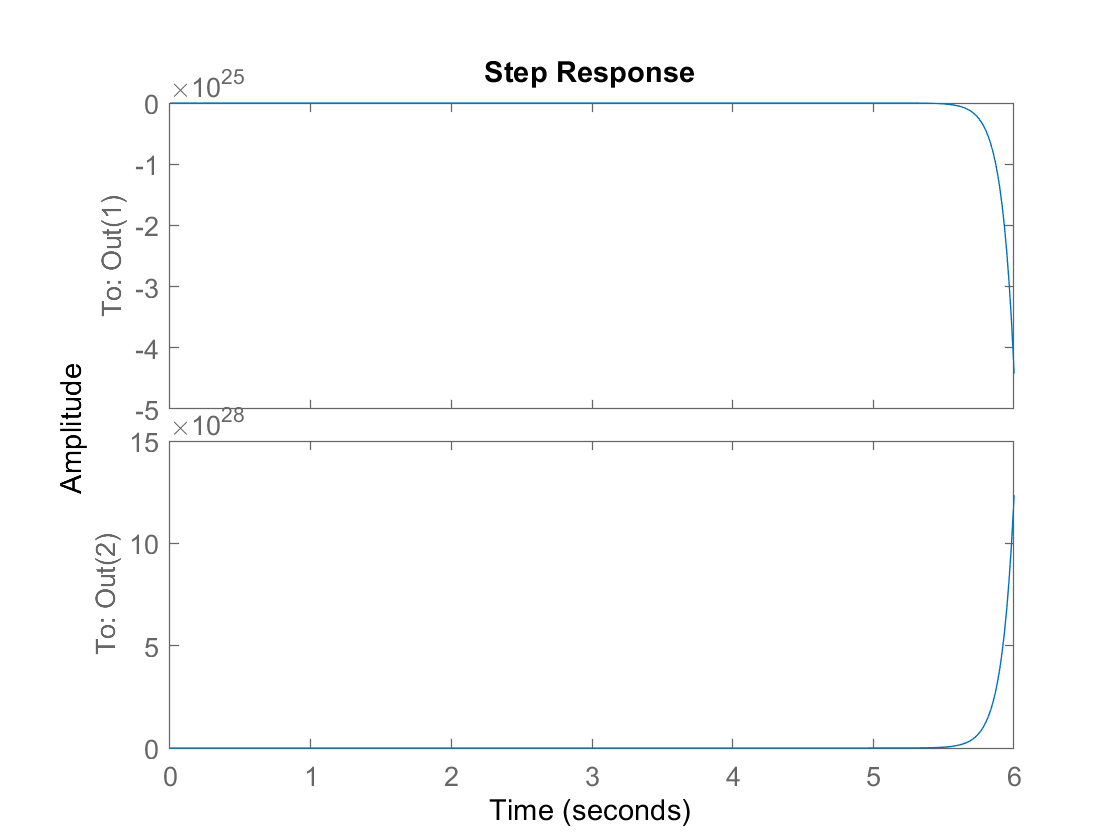

step(sys)

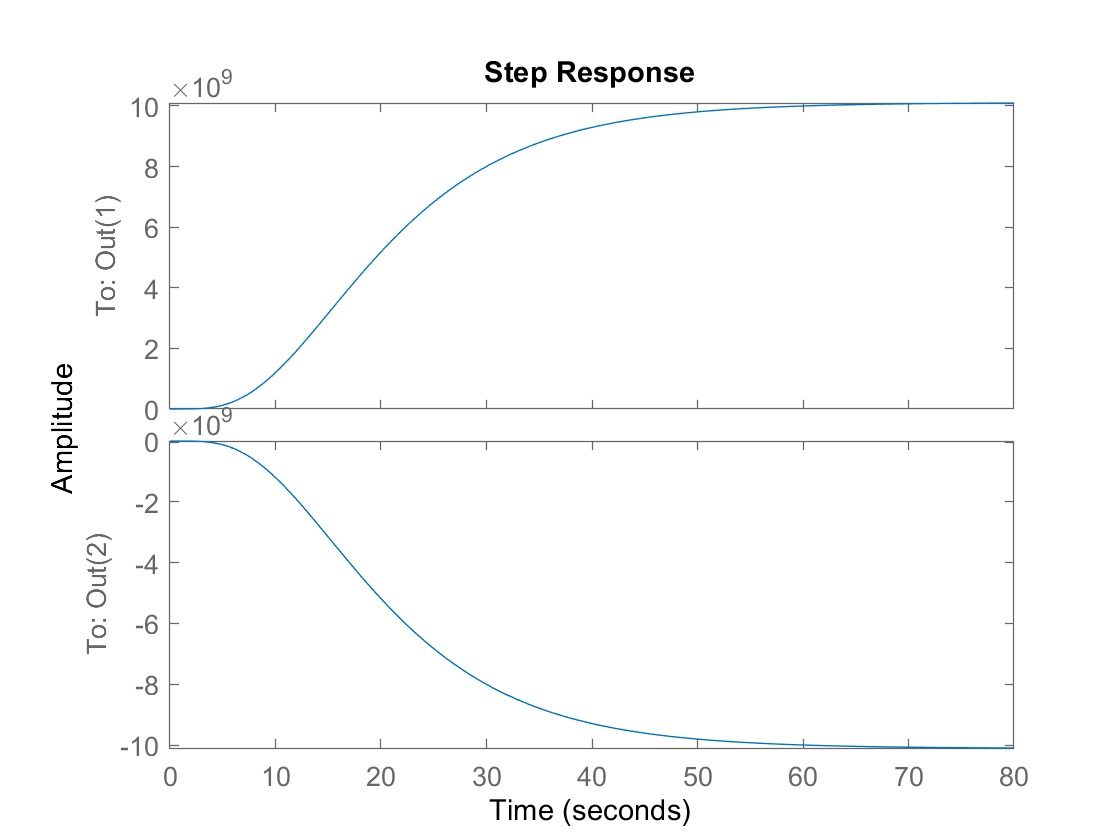

step(syscl)